% judp.m--Uses Matlab's Java interface to handle User Datagram Protocol
% (UDP) communications with another application, either on the same
% computer or a remote one. 
%
% JUDP('SEND',PORT,HOST,MSSG) sends a message to the specifed port and
% host. HOST can be either a hostname (e.g., 'www.example.com') or a string
% representation of an IP address (e.g., '192.0.34.166'). PORT, the port
% number on the target machine, is an integer port number between 1025 and
% 65535. The specified port must be open in the receiving machine's
% firewall. If PORT is a 2-element vector of integers, rather than a single
% integer, the first element represents the target (receiving) port number
% as before, while the second element represents the local (source) port.
% 
% MSSG = JUDP('RECEIVE',PORT,PACKETLENGTH) receives a message over the
% specified port. PACKETLENGTH should be set to the maximum expected
% message length to be received in the UDP packet; if too small, the
% message will be truncated.
%
% MSSG = JUDP('RECEIVE',PORT,PACKETLENGTH,TIMEOUT) attempts to receive a
% message but times out after TIMEOUT milliseconds. If TIMEOUT is not
% specified, as in the previous example, a default value is used.
%
% [MSSG,SOURCEHOST] = JUDP('RECEIVE',...) returns a string representation
% of the originating host's IP address, in addition to the received
% message. 
%
% Messages sent by judp.m are in int8 format. The int8.m function can be
% used to convert integers or characters to the correct format (use
% double.m or char.m to convert back after the datagram is received). 
% Non-integer values can be converted to int8 format using typecast.m (use
% typecast.m to convert back).
% 
% e.g.,   mssg = judp('receive',21566,10); char(mssg')
%         judp('send',21566,'208.77.188.166',int8('Howdy!'))         
%
% e.g.,   [mssg,sourceHost] = judp('receive',21566,10,5000)
%         judp('send',21566,'www.example.com',int8([1 2 3 4]))
%         
% e.g.,   mssg = judp('receive',21566,200); typecast(mssg,'double')
%         judp('send',21566,'localhost',typecast([1.1 2.2 3.3],'int8'))
% Developed in Matlab 7.8.0.347 (R2009a) on GLNX86.
% Kevin Bartlett (kpb@uvic.ca), 2009-06-18 16:11
%-------------------------------------------------------------------------
%-------------------------------------------------------------------------
% REVISION HISTORY
% 
% 2021-07-05: At suggestion of Dennie Craane, added ability to specify both
% a source port number and a target port number when sending packets.
%-------------------------------------------------------------------------

MSSG = judp('RECEIVE', 8080, 1000)

MSSG = 1000×1 int8 column vector
    0
    0
    0
    1
    1
    2
    3
    5
    7
   10


X = int16(MSSG);
for i= 1:1000
    if (X(i) < 0)
        X(i) = X(i) + 255;
    else
        X(i) = X(i);
    end
end
X0 = X(1:500);
X1 = X(501:1000);
Y = X1 * 255 + X0;
t = 0:0.01:5-0.01;
save('servo.mat','t','Y');


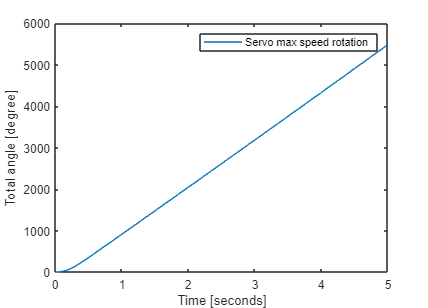

load("servo.mat");
plot(t,Y)
legend('Servo max speed rotation');
xlabel('Time [seconds]');
ylabel('Total angle [degree]');